[https://www.youtube.com/watch?v=GCVK3w5DHbk&t=4s](https://www.youtube.com/watch?v=GCVK3w5DHbk&t=4s)

in this video the plane need arround 3 seconds for 1 circle

$\frac{X\left\lbrack m\right\rbrack }{3s}=222\left\lbrack \frac{m}{s}\right\rbrack \to X=666m$ this is the diameter of the circle.

clc; clear;
% Parameters for Glider Movement
v_target = 800 / 3.6;  % Target speed in m/s (converted from km/h)
a_constant = 100 /3.6 % wind speed

a_constant = 27.7778

r = 666/2;  % Radius in meters
a_turn = v_target^2 / r;  % Base acceleration in m/s² (constant for reference)
G = a_turn / 9.81  % Base G-force

G = 15.1169


% Simulation parameters
accelerometer_rate = 6400;  % Accelerometer sampling rate in Hz
real_sampling_rate = accelerometer_rate*10;  % High resolution sampling rate for real values (10x accelerometer rate)

timeMinutes = 3;  % Duration in minutes
time_duration = timeMinutes * 60;  % Duration of simulation in seconds

% Time steps
real_time_steps = real_sampling_rate * time_duration;  % High resolution steps
accelerometer_steps = accelerometer_rate * time_duration;  % Accelerometer resolution steps
real_dt = 1 / real_sampling_rate;  % Time step for real values
accelerometer_dt = 1 / accelerometer_rate;  % Time step for measured values

% Time arrays
real_time = linspace(0, time_duration, real_time_steps);  % High resolution time array
accelerometer_time = linspace(0, time_duration, accelerometer_steps);  % Accelerometer time array

% Arrays to store speed and acceleration
real_speed = zeros(1, real_time_steps);
real_acceleration = zeros(1, real_time_steps);

% Sinusoidal acceleration example with a positive bias
frequency = 1/3;  % Frequency of the oscillation (in Hz)
amplitude = 0.7 * a_constant;  % Amplitude of oscillation (70% of the base acceleration)
bias = 0.045 * a_constant;  % Positive bias to ensure more positive acceleration

% Modified acceleration with both positive and negative values
real_acceleration = bias + amplitude * sin(2 * pi * frequency * real_time);  % High-res biased sinusoidal acceleration


% Simulate real speed using high-resolution acceleration data
for i = 2:real_time_steps
    real_speed(i) = real_speed(i-1) + real_acceleration(i) * real_dt;  % v = v_0 + a * dt
end

% Noise parameters for low noise mode at 6400 Hz
rms_noise = 0.3;  % RMS noise in m/s² (based on 3 LSB at 3200 Hz) (100 mg/LSB ) (3LSB=3×0.1m/s^2 =0.3m/s^2 .)

sampling_bandwidth_ratio = sqrt(accelerometer_rate / 3200);  % Adjust for 6400 Hz ODR
adjusted_rms_noise = rms_noise * sampling_bandwidth_ratio;

% Add realistic noise to the downsampled accelerometer data
measured_acceleration = interp1(real_time, real_acceleration, accelerometer_time) + ...
                        adjusted_rms_noise * randn(1, accelerometer_steps);  % Add realistic noise

measured_speed = zeros(1, accelerometer_steps);

% Simulate measured speed using noisy, low-resolution acceleration
for i = 2:accelerometer_steps
    measured_speed(i) = measured_speed(i-1) + measured_acceleration(i) * accelerometer_dt;  % v = v_0 + a * dt
end

% Display maximum speeds reached
disp(['Maximum real speed: ', num2str(max(real_speed)), ' m/s']);

Maximum real speed: 241.7122 m/s


disp(['Maximum measured speed: ', num2str(max(measured_speed)), ' m/s']);

Maximum measured speed: 241.6789 m/s




% Interpolate real acceleration to accelerometer time points
interpolated_real_acceleration = interp1(real_time, real_acceleration, accelerometer_time);

% Calculate speed divergence (integration of the acceleration difference)
divergence_speed = cumtrapz(accelerometer_time, measured_acceleration - interpolated_real_acceleration);

% Display divergence statistics
disp(['Final speed divergence: ', num2str(divergence_speed(end)), ' m/s']);

Final speed divergence: -0.035377 m/s


disp(['Mean absolute speed divergence: ', num2str(mean(abs(divergence_speed))), ' m/s']);

Mean absolute speed divergence: 0.023122 m/s


disp(['Maximum absolute speed divergence: ', num2str(max(abs(divergence_speed))), ' m/s']);

Maximum absolute speed divergence: 0.057831 m/s





% Find the divergence in speed over time
divergence_speed = cumtrapz(accelerometer_time, measured_acceleration - interpolated_real_acceleration);

% Find the indices of maximum and minimum divergence
[~, max_idx] = max(divergence_speed);
[~, min_idx] = min(divergence_speed);

% Extract corresponding time points and divergence values
max_divergence_time = accelerometer_time(max_idx);
min_divergence_time = accelerometer_time(min_idx);

max_divergence_value = divergence_speed(max_idx);
min_divergence_value = divergence_speed(min_idx);

% Display the two points with maximum and minimum divergence
disp('Data point with maximum positive divergence:');

Data point with maximum positive divergence:


disp(['Time: ', num2str(max_divergence_time), ' s']);

Time: 51.0377 s


disp(['Divergence: ', num2str(max_divergence_value), ' m/s']);

Divergence: 0.047821 m/s



disp('Data point with maximum negative divergence:');

Data point with maximum negative divergence:


disp(['Time: ', num2str(min_divergence_time), ' s']);

Time: 146.2345 s


disp(['Divergence: ', num2str(min_divergence_value), ' m/s']);

Divergence: -0.057831 m/s


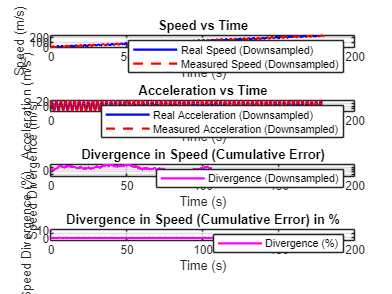

% Downsample factors for plotting
downsample_factor_real = 100;  % For high-resolution data
downsample_factor_accel = 10;  % For accelerometer data

% Downsample data
real_time_ds = real_time(1:downsample_factor_real:end);
accelerometer_time_ds = accelerometer_time(1:downsample_factor_accel:end);

% Compute divergence
divergence_speed = cumtrapz(accelerometer_time, measured_acceleration - ...
    interp1(real_time, real_acceleration, accelerometer_time));

% Downsample divergence for plotting
divergence_speed_ds = divergence_speed(1:downsample_factor_accel:end);

% Plot results
figure;

% Plot real and measured speeds
subplot(4, 1, 1);
plot(real_time_ds, real_speed(1:downsample_factor_real:end), 'b-', 'LineWidth', 1.5); 
hold on;
stairs(accelerometer_time_ds, measured_speed(1:downsample_factor_accel:end), 'r--', 'LineWidth', 1.5); 
title('Speed vs Time');
xlabel('Time (s)');
ylabel('Speed (m/s)');
legend('Real Speed (Downsampled)', 'Measured Speed (Downsampled)');
grid on;

% Plot real and measured accelerations
subplot(4, 1, 2);
plot(real_time_ds, real_acceleration(1:downsample_factor_real:end), 'b-', 'LineWidth', 1.5); 
hold on;
stairs(accelerometer_time_ds, measured_acceleration(1:downsample_factor_accel:end), 'r--', 'LineWidth', 1.5); 
title('Acceleration vs Time');
xlabel('Time (s)');
ylabel('Acceleration (m/s²)');
legend('Real Acceleration (Downsampled)', 'Measured Acceleration (Downsampled)');
grid on;

% Plot divergence
subplot(4, 1, 3);
plot(accelerometer_time_ds, divergence_speed_ds, 'm-', 'LineWidth', 1.5);
title('Divergence in Speed (Cumulative Error)');
xlabel('Time (s)');
ylabel('Speed Divergence (m/s)');
legend('Divergence (Downsampled)');
grid on;
% Compute divergence in percentage
real_speed_interp = interp1(real_time, real_speed, accelerometer_time);
divergence_percentage = 100 * (divergence_speed ./ real_speed_interp); % In percentage

% Downsample divergence for plotting
divergence_percentage_ds = divergence_percentage(1:downsample_factor_accel:end);

% Plot divergence in percentage
subplot(4, 1, 4);
plot(accelerometer_time_ds, divergence_percentage_ds, 'm-', 'LineWidth', 1.5);
title('Divergence in Speed (Cumulative Error) in %');
xlabel('Time (s)');
ylabel('Speed Divergence (%)');
legend('Divergence (%)');
grid on;